## Problema T5.5. 

**Interpolación mediante spline cúbicas con polinomios de  Lagrange**

a) Escribe una función de MATLAB para la interpolación con splines  cúbicas naturales mediante polinomios de Lagrange de tercer grado.

- Véase SplineCub.m adjunta.

b) Los valores de la entalpía por unidad de masa, h, de un plasma de  argón en equilibrio (Ar, Ar+, A++, A+++ iones y electrones) frente a la  temperatura son:

T = [5, 7.5, 10, 12.5, 15, 17.5, 20, 22.5, 25, 27.5, 30]; % T x 10^3 K
h = [3.3, 7.5, 41.8, 51.8, 61, 101.1, 132.9, 145.5, 171.4, 225.8, 260.9];% h (Mg/kg)

*Nota: Las unidades de la Temperatura (T) son Kelvin y las unidadesde la entalpía por unidad de masa (h) son Mg/kg.*

Escribe un programa en un archivo de script que utilice la interpolación mediante la función SplineCub para generar una gráfica que muestre las curvas  de interpolación (splines), y los puntos de datos de la tabla (utiliza círculos rojos  para los puntos).

dibujo_spline

Calcula la entalpía por unidad de masa a T = 14000 ºK y T = 24000 ºK.

T1 = 14;
T2 = 24;
h1 = SplineCub(T, h, T1)

h1 = 54.8977

h2 = SplineCub(T, h, T2)

h2 = 157.1903

h1_matlab = spline(T, h, T1)

h1_matlab = 54.1947

h2_matlab = spline(T, h, T2)

h2_matlab = 157.3501

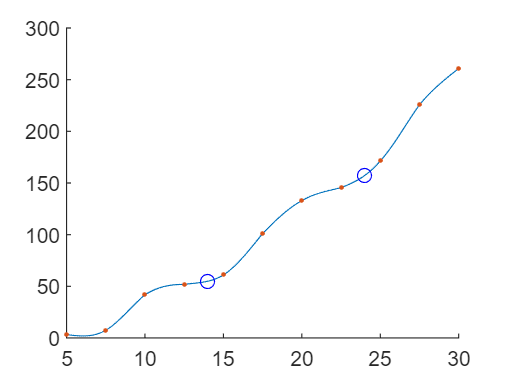

plot(T, h, '.', LineWidth=100)
plot(T1, h1, 'bo')
plot(T2, h2, 'bo')
hold off